# **Visión Artificial. GIEC-GITT.**

# **Sistemas de Visión Artificial. GII-GIC-GISI.**

 **Sira Palazuelos, Miguel Angel Garcia, Juan Manuel Miguel**

 **Departamento de Electrónica. Universidad de Alcalá.**

**Nombre: Alejandro Fernández Ambrós, Cristina Martínez Toledo**

**Fecha: 20/11/2026**

# Tema 4. Ejercicio 3. *Local Features*

El objetivo de esta práctica es mostrar el potencial de las denominadas "*Local Features*". Para ello se va a buscar un objeto dentro de una escena utilizando los detectores y descriptores de características locales.

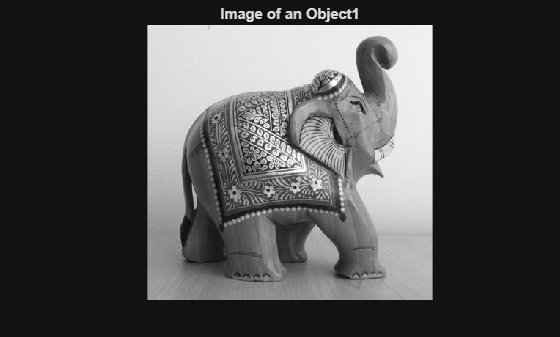

clear all

close all

Step 1) Leer la imagen de referencia que contiene el objeto de interés.

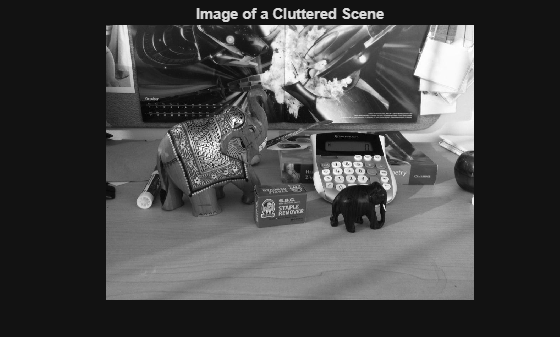

Object1Image = imread('elephant.jpg');

 
figure;
imshow(Object1Image);
title('Image of an Object1');

Se lee la escena que contiene al objeto de interés.

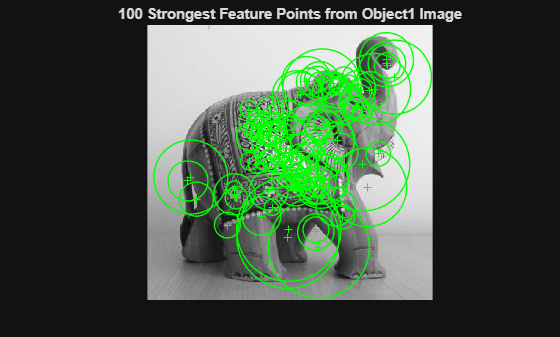

sceneImage = imread('clutteredDesk.jpg');

figure; 
imshow(sceneImage);
title('Image of a Cluttered Scene');

 Step 2) Se detectan las características locales del objeto y de la escena:

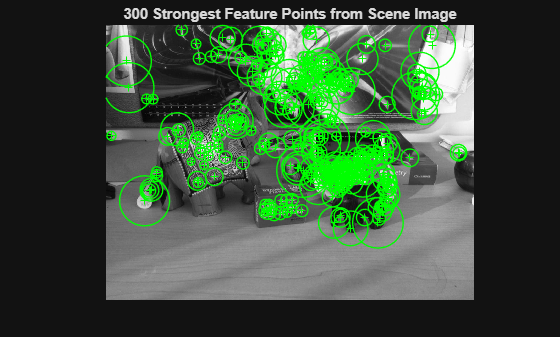

% Detect feature points in both images.
Object1Points = detectSURFFeatures(Object1Image);

scenePoints = detectSURFFeatures(sceneImage);

Se visualizan los puntos más fuertes que se encuentran en la imagen del objeto de referencia:

figure; 

numMatches = 12

imshow(Object1Image);
title('100 Strongest Feature Points from Object1 Image');
hold on;
plot(selectStrongest(Object1Points, 100));

Se visualizan los puntos más fuertes que se encuentran en la imagen de la escena

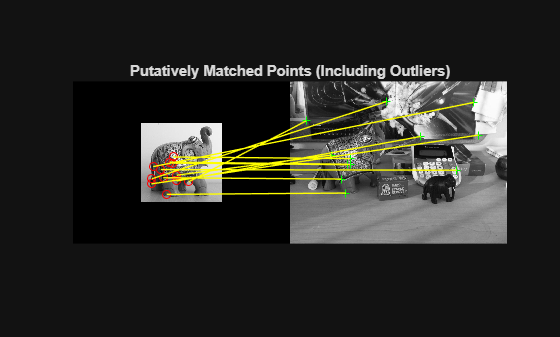

figure; 

imshow(sceneImage);
title('300 Strongest Feature Points from Scene Image');
hold on;
plot(selectStrongest(scenePoints, 300));

numInliers = 4

Step 3) Se extraen los descriptores de caracterísitcas de ambas imágenes.

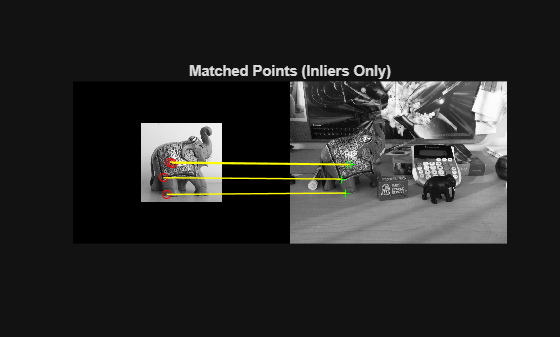

[Object1Features, Object1Points] = extractFeatures(Object1Image, Object1Points);

[sceneFeatures, scenePoints] = extractFeatures(sceneImage, scenePoints);

Step 4) Se encuentran las coincidencias (*matches*) y se visualizan.

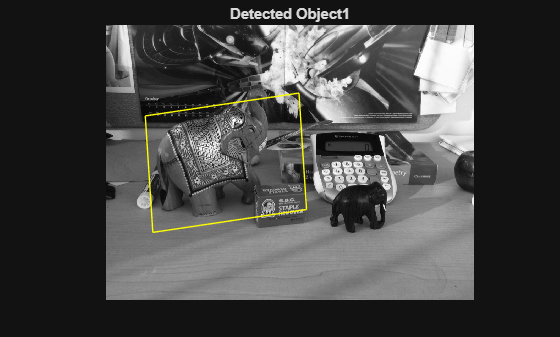

Object1Pairs = matchFeatures(Object1Features, sceneFeatures, 'MaxRatio', 0.9);

numMatches = size(Object1Pairs,1)
matchedObject1Points = Object1Points(Object1Pairs(:, 1), :);
matchedScenePoints = scenePoints(Object1Pairs(:, 2), :);
figure;
showMatchedFeatures(Object1Image, sceneImage, matchedObject1Points, ...
    matchedScenePoints, 'montage');
title('Putatively Matched Points (Including Outliers)');

Step 5) Se localiza el objeto en la escena usando las coincidencias. 

`estimateGeometricTransform` calcula la transformación relacionando los puntos coincidentes, a la vez que elimina los valores outliers. Esta transformación nos permite localizar el objeto en la escena.

Sin ruido: 11 emparejamientos
    247   1611
    442    947
    513   1148
    587   1074
    590   1075
    598   1092
    618   1125
    656   1159
    708   1541
    719   2050
    722   2050



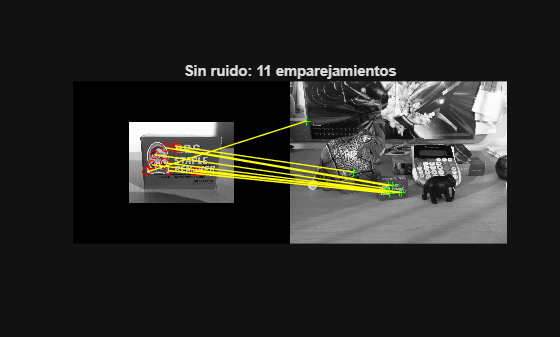

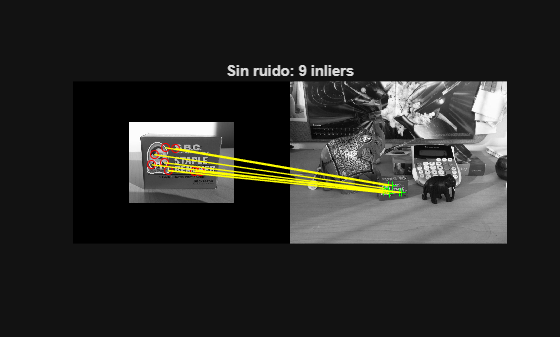

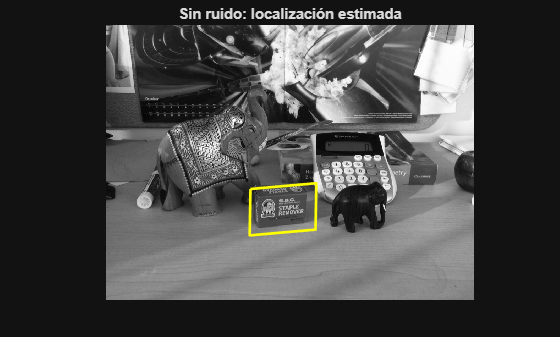

[tform, inlierObject1Points, inlierScenePoints] = estimateGeometricTransform(matchedObject1Points, matchedScenePoints, 'affine');

numInliers = inlierObject1Points.Count
figure;
showMatchedFeatures(Object1Image, sceneImage, inlierObject1Points, inlierScenePoints, 'montage');
title('Matched Points (Inliers Only)');

Se obtiene el polígono delimitador de la imagen de referencia.

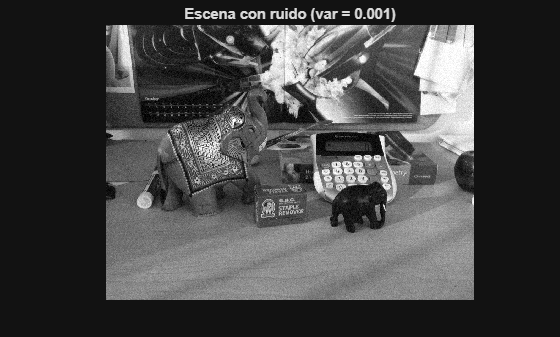

Object1Polygon = [1, 1;...                           % top-left

Ruido var 0.001: 7 emparejamientos
    147    937
    597   1225
    639   1308
    695   1265
    708   1677
    719   2196
    722   2196



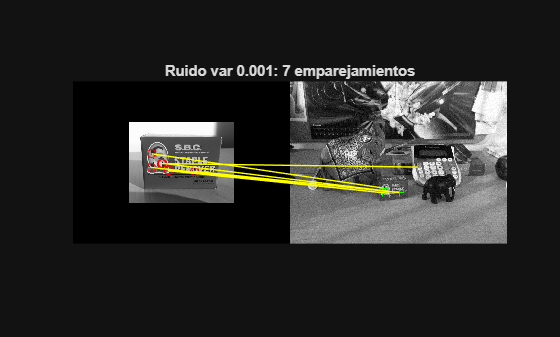

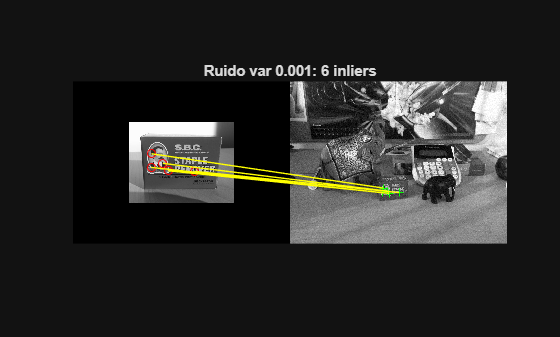

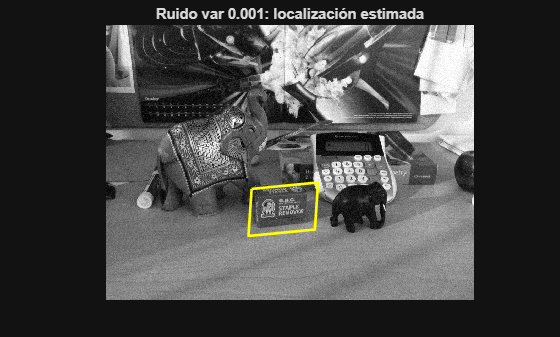

        size(Object1Image, 2), 1;...                 % top-right
        size(Object1Image, 2), size(Object1Image, 1);... % bottom-right

        1, size(Object1Image, 1);...                 % bottom-left
        1, 1];                   % top-left again to close the polygon 

Se transforma el polígono en el sistema de coordenadas de la imagen de destino. El polígono transformado indica la ubicación del objeto1 en la escena.

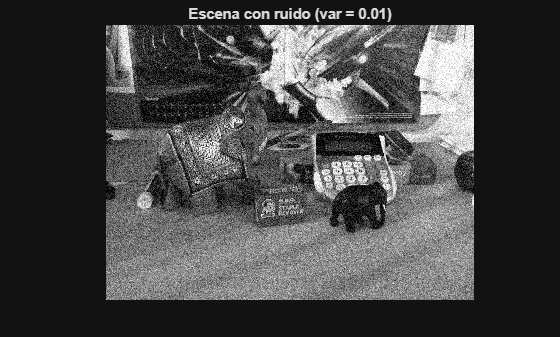

newObject1Polygon = transformPointsForward(tform, Object1Polygon);    

Ruido var 0.01: 4 emparejamientos
      1   6391
     77   1615
    278   8529
    330    768



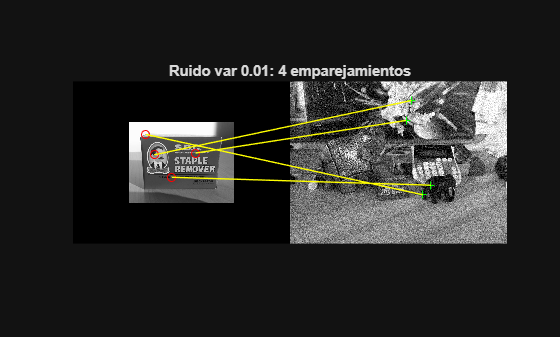

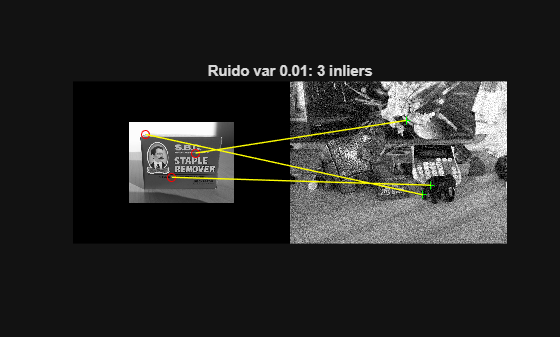

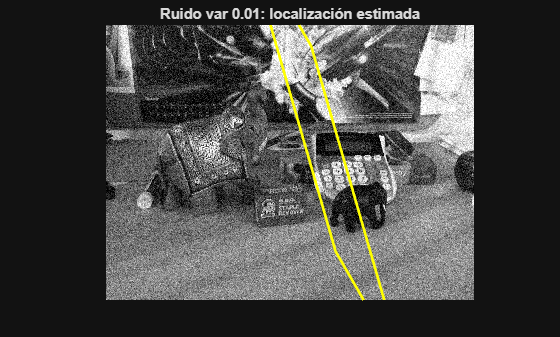


figure;

imshow(sceneImage);
hold on;
line(newObject1Polygon(:, 1), newObject1Polygon(:, 2), 'Color', 'y');
title('Detected Object1');

Se pide:

- Repita el proceso anterior pero buscando otro objeto de la escena, en este caso la caja de la grapadora, cuya imagen es `'stapleRemover.jpg'`. Además utilice el detector y descriptor BRISK ([`detectBRISKFeatures`](https://es.mathworks.com/help/vision/ref/detectbriskfeatures.html)). Compruebe cuántos pares de puntos empareja el algoritmo visualizando la salida de la función **matchFeatures**.

- Añada ruido gaussiano de varianza `0.001` a la imagen `'clutteredDesk.jpg'` y repita el apartado anterior. Compare el número de emparejamientos y de `inliers` con los obtenidos sin ruido. ¿Sigue siendo posible localizar correctamente el objeto?

- Repita el apartado anterior utilizando ruido gaussiano de varianza `0.01`. Compare nuevamente el número de emparejamientos y de `inliers`. ¿Es posible localizar el objeto?

- Aplique a la imagen ruidosa alguna técnica de reducción de ruido estudiada previamente y repita el proceso. ¿Mejora el resultado? Justifique la respuesta a partir del número de correspondencias obtenidas y de la localización final del objeto.

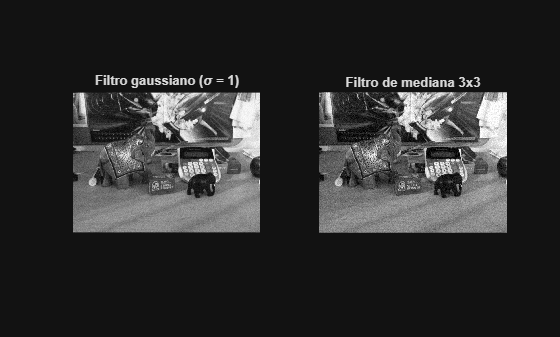


%% Apartado 1: buscar la grapadora con BRISK (sin ruido)
objImg = imread('stapleRemover.jpg');   % objeto a buscar

Ruido 0.01 + gaussiano: 4 emparejamientos
   278    31
   575    38
   610   194
   656   208



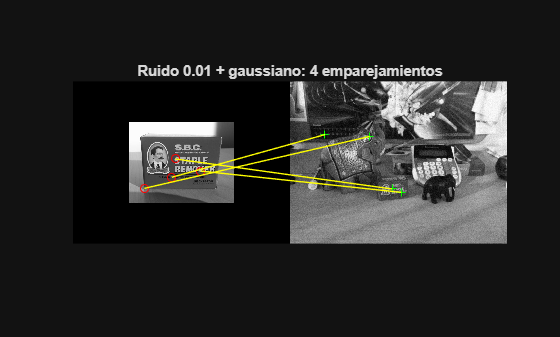

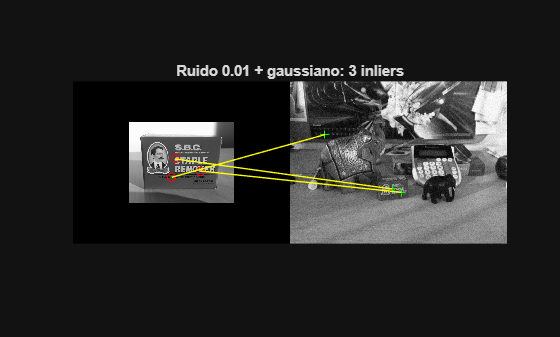

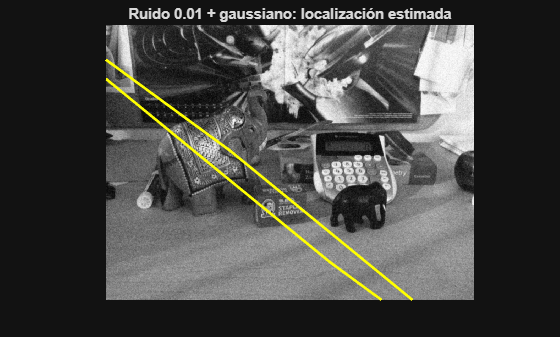

Ruido 0.01 + mediana: 7 emparejamientos
    278    119
    573    956
    598    626
    617    650
    656    673
    719   1207
    722   1207



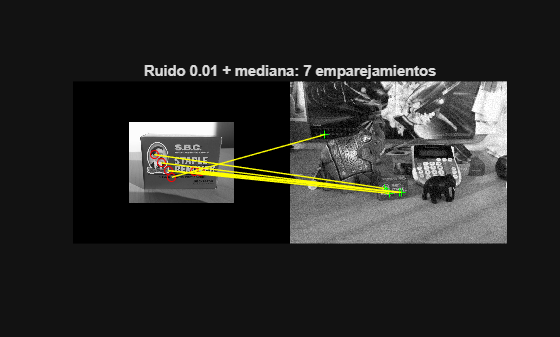

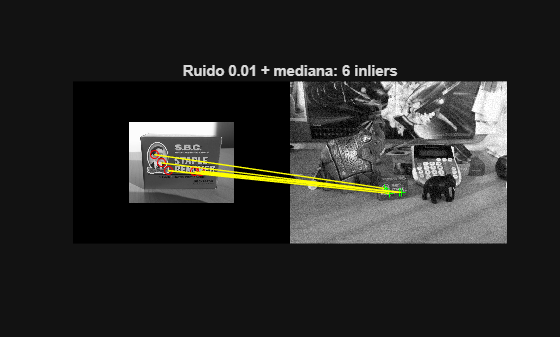

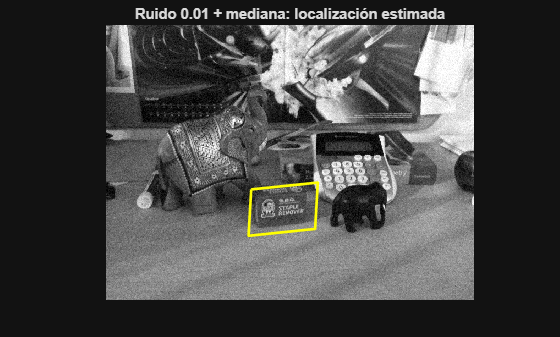

sceneImage = imread('clutteredDesk.jpg');   % escena
rng(0, 'twister'); % Repetimos el experimento con el mismo ruido cada vez.

% buscarObjeto (definida al final) hace todo el proceso y devuelve:
% nº de puntos detectados en la escena, nº de emparejamientos y nº de inliers
[p1, m1, i1] = buscarObjeto(objImg, sceneImage, 'Sin ruido');

%% Apartado 2: ruido gaussiano de varianza 0.001
% imnoise(imagen, 'gaussian', media, varianza). Trabaja con la imagen
% escalada a [0,1]: varianza 0.001 equivale a una desviación típica de
% ~0.03, unos 8 niveles de gris de 255

tablaResumen = 5×4 table
                 'Sin ruido'    2462    11    9
               'Ruido 0.001'    2608     7    6
                'Ruido 0.01'    9933     4    3
    'Ruido 0.01 + gaussiano'    1139     4    3
      'Ruido 0.01 + mediana'    1783     7    6


escenaRuido1 = imnoise(sceneImage, 'gaussian', 0, 0.001);
figure; imshow(escenaRuido1); title('Escena con ruido (var = 0.001)');

[p2, m2, i2] = buscarObjeto(objImg, escenaRuido1, 'Ruido var 0.001');

%% Apartado 3: ruido gaussiano de varianza 0.01
% Partimos otra vez de la escena original. La desviación típica es de unos 25 niveles de gris.
escenaRuido2 = imnoise(sceneImage, 'gaussian', 0, 0.01);
figure; imshow(escenaRuido2); title('Escena con ruido (var = 0.01)');

[p3, m3, i3] = buscarObjeto(objImg, escenaRuido2, 'Ruido var 0.01');

%% Apartado 4: reducir el ruido y repetir
% Filtro gaussiano (suaviza promediando cada píxel con sus vecinos;
% adecuado para ruido gaussiano). El 1 es la sigma: cuánto suaviza
escenaFiltradaG = imgaussfilt(escenaRuido2, 1);

% Filtro de mediana 3x3 (cada píxel se sustituye por la mediana de su
% vecindad 3x3; reduce ruido conservando mejor los bordes)
escenaFiltradaM = medfilt2(escenaRuido2, [3 3]);

figure
subplot(1,2,1); imshow(escenaFiltradaG); title('Filtro gaussiano (\sigma = 1)');
subplot(1,2,2); imshow(escenaFiltradaM); title('Filtro de mediana 3x3');

[p4, m4, i4] = buscarObjeto(objImg, escenaFiltradaG, 'Ruido 0.01 + gaussiano');
[p5, m5, i5] = buscarObjeto(objImg, escenaFiltradaM, 'Ruido 0.01 + mediana');

%% Tabla resumen para comparar todos los casos
Caso = {'Sin ruido'; 'Ruido 0.001'; 'Ruido 0.01'; ...
    'Ruido 0.01 + gaussiano'; 'Ruido 0.01 + mediana'};
PuntosEscena = [p1; p2; p3; p4; p5];
Emparejamientos = [m1; m2; m3; m4; m5];
Inliers = [i1; i2; i3; i4; i5];
tablaResumen = table(Caso, PuntosEscena, Emparejamientos, Inliers)


## Qué pasa con el ruido y el filtrado

Sin ruido salen 11 emparejamientos y 9 son compatibles con la transformación. En la figura se ve que el polígono amarillo rodea la caja, delante del teléfono. Con varianza 0,001 bajamos a 7 emparejamientos y 6 inliers. Se pierden algunas parejas, pero las que quedan todavía sitúan bien la caja. En los montajes de inliers, las líneas salen del logotipo y las letras de la foto de referencia y llegan a esa misma cara de la caja en la escena. Con el ruido leve quedan menos líneas, pero siguen concentradas en esa zona. El polígono amarillo mantiene la inclinación de la caja y cubre casi la misma zona que en la imagen sin ruido.

Con varianza 0,01 aparecen 9.933 puntos en la escena frente a los 2.462 de la original, aunque solo quedan 4 emparejamientos y 3 inliers. El ruido crea cambios de intensidad que BRISK puede tomar por esquinas y también altera los detalles que usa para comparar puntos. En el montaje de inliers, las líneas se abren y una de ellas termina muy por encima de la caja, cerca del fondo de la escena. En la imagen final, los lados del polígono bajan casi en vertical junto al teléfono y salen por el borde inferior. La caja queda a un lado. Tres parejas no colineales bastan para ajustar una transformación afín, incluso si son parejas equivocadas. Por eso el recuento de inliers por sí solo no confirma la localización.

Los dos filtros reducen mucho la cantidad de puntos detectados. Con el gaussiano seguimos en 4 emparejamientos y 3 inliers, y el polígono cruza la escena en diagonal. Con la mediana subimos a 7 emparejamientos y 6 inliers, y el polígono vuelve a rodear la caja. En su montaje se ve que las líneas vuelven a juntarse sobre la cara impresa de la caja. En la imagen final, el lado superior del polígono sigue el borde inclinado de esa cara y el lado derecho queda antes del elefante negro. En esta prueba la mediana sí ayuda. Una posible razón es que reduce parte del ruido sin suavizar tanto los bordes y las letras que BRISK utiliza para encontrar las parejas.


%% Función auxiliar
function [numPuntosEscena, numMatches, numInliers] = buscarObjeto(objImg, escena, nombre)
% Repetimos los mismos pasos de BRISK para que los casos sean comparables.
objPoints = detectBRISKFeatures(objImg);
scenePoints = detectBRISKFeatures(escena);
numPuntosEscena = scenePoints.Count;
[objFeatures, objPoints] = extractFeatures(objImg, objPoints);
[sceneFeatures, scenePoints] = extractFeatures(escena, scenePoints);

% Cada fila contiene el índice del punto del objeto y el de su pareja en la escena.
% MaxRatio descarta parejas ambiguas, cuando los dos mejores candidatos son muy parecidos.
pares = matchFeatures(objFeatures, sceneFeatures, 'MaxRatio', 0.9);
numMatches = size(pares, 1);
fprintf('%s: %d emparejamientos\n', nombre, numMatches);
disp(pares)

matchedObj = objPoints(pares(:, 1), :);
matchedScene = scenePoints(pares(:, 2), :);
figure
showMatchedFeatures(objImg, escena, matchedObj, matchedScene, 'montage');
title(sprintf('%s: %d emparejamientos', nombre, numMatches));

numInliers = 0;
if numMatches < 3
    % Una transformación afín necesita al menos tres parejas no colineales.
    figure
    imshow(escena)
    title([nombre, ': menos de tres emparejamientos']);
    return
end

[tform, inlierObj, inlierScene, estado] = ...
    estimateGeometricTransform(matchedObj, matchedScene, 'affine');
if estado ~= 0
    figure
    imshow(escena)
    title([nombre, ': no se pudo estimar la transformación']);
    return
end

numInliers = inlierObj.Count;
figure
showMatchedFeatures(objImg, escena, inlierObj, inlierScene, 'montage');
title(sprintf('%s: %d inliers', nombre, numInliers));

% Transformamos las cuatro esquinas de la foto de referencia para ver
% dónde cae el rectángulo de la caja dentro de la escena.
ancho = size(objImg, 2);
alto = size(objImg, 1);
poligono = [1 1; ancho 1; ancho alto; 1 alto; 1 1];
nuevoPoligono = transformPointsForward(tform, poligono);

figure
imshow(escena)
hold on
plot(nuevoPoligono(:, 1), nuevoPoligono(:, 2), 'y-', 'LineWidth', 2);
hold off
title([nombre, ': localización estimada']);
end